tim_freq_hz = 40000000;
tsf_freq_hz =  1000000;
samplerate_hz = 100;
chunk_length_s = 1:1:30;


data = dlmread('./data/esp32ap_10ms_24hr.txt');
tim_timestamps_arr = data(:,1) - data(1,1);
tsf_timestamps_arr   = data(:,2) - data(1,2);

% Compute linear fit
p = polyfit(tim_timestamps_arr, tsf_timestamps_arr, 1);

Error accumulated within time

tsf_predicted = polyval(p, tim_timestamps_arr);
error_tsf = tsf_predicted - tsf_timestamps_arr - tsf_predicted(1);

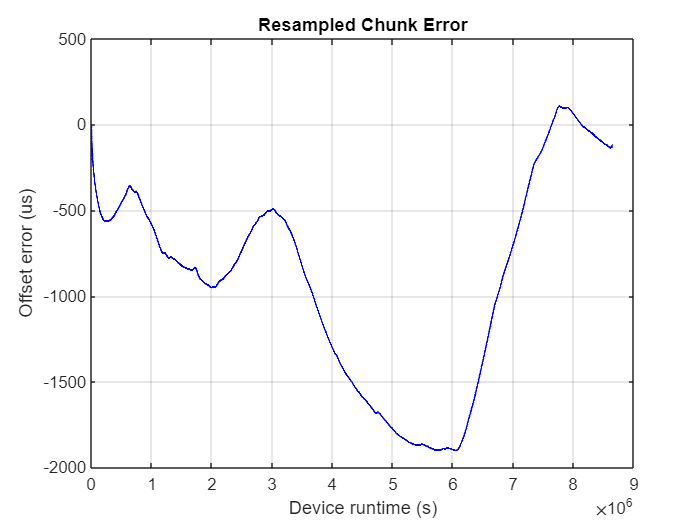

new_length = 24000;
chunks_tttt = 1:1:length(error_tsf);

% Resample data to reduce the number of points
%new_length = floor(length(error_tsf) / factor);
error_resampled = resample(error_tsf, new_length, length(error_tsf));
chunks_resampled = linspace(1, length(error_tsf), new_length);

% Plot the resampled data
figure;
plot(chunks_resampled, error_resampled, 'b-', 'LineWidth', 1);
xlabel('Device runtime (s)');
ylabel('Offset error (us)');
title('Resampled Chunk Error');
grid on;